assert(isfile("DCS_2D_Cylinder.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

cylinder.radius = 30e-3; % (m)
cylinder.height = 20e-3; % (m)
cylinder.n_r = 10;
cylinder.n_z = 10;

## Uniform Grid

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length  = 4.00e-3; % length (m)

EM.z = 5.00e-3; % (m)

EM.current = 1; % (A)
EM.Nturns = 60;
EM.current_density = EM.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.angular_frequency = 2*pi*2000; % (rad/s)

#### Model

vertex_file = 'uniform_grid_vertex.txt';
element_file = 'uniform_grid_element.txt';

[r,z] = meshgrid( ...
    linspace(0, cylinder.radius, cylinder.n_r+1), ...
    linspace(-cylinder.height,0, cylinder.n_z+1)     );
r = reshape(r', [],1);
z = reshape(z', [],1);
vertex_data = [(1:numel(r))' r z];
writematrix(vertex_data, vertex_file);

element_data(1,:) = [1 2 cylinder.n_r+3 cylinder.n_r+2];
for i = 2:cylinder.n_r*cylinder.n_z
    if mod(i,cylinder.n_r) == 1; offset = 2; else; offset = 1; end
    element_data(i,:) = element_data(i-1,:) + offset;
end
element_data = [(1:size(element_data,1))' element_data];
writematrix(element_data, element_file);
clear r z vertex_data element_data i offset

Model = struct;
Model = LoadModel2D(Model, vertex_file, element_file, 1);

calculate geometry took 0.00 seconds


clear vertex_file element_file

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 3.91 seconds


#### Solve in frequency domain

Sol = SolveFrequency2D(GoverningEquation, EM);

solve J_Im took 0.00 seconds
solve J_Re took 0.00 seconds


#### Plot result

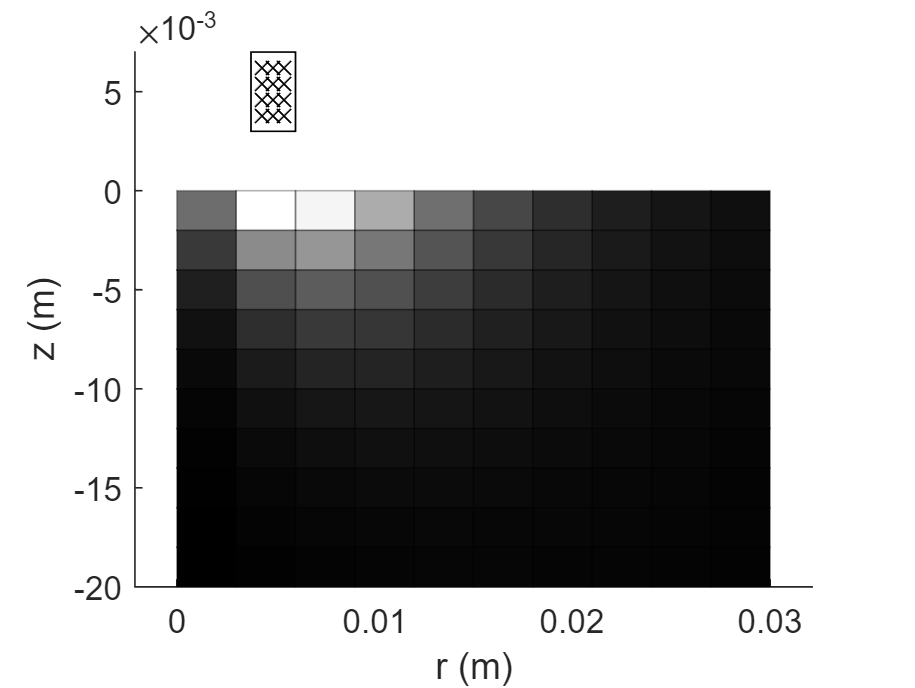

J = hypot(Sol.J_Re, Sol.J_Im);
pos = Model.elms_center;

PlotWorld2D(Model, EM, J);